# Script for area-to-point kriging (A2PK)

This script shows you how to use the function `A2PK.m`

The same examples as in `./exemples/` folder are given below with less details.

addpath('./FastGaussianSimulation');
addpath('./functions');

## Unconditional simulation

Generating input data

covar.model='spherical'; covar.range=[20 20]; covar.var=1; covar.azimuth=0;
covar = covarIni(covar);

z.x=1:100;
z.y=1:100;
[z.X,z.Y] = meshgrid(z.x, z.y);
z.nxy = numel(z.X);
z.s = [numel(z.x) numel(z.y)];
z.true = FGS(z, covar);
z.true = z.true{1};

Z.dx=4;Z.dy=4;
Z.x = Z.dx/2:Z.dx:z.x(end);
Z.y = Z.dy/2:Z.dy:z.y(end);
[Z.X,Z.Y] = meshgrid(Z.x, Z.y);

G = zeros(numel(Z.X),z.nxy);
for ij=1:z.nxy
     [~,id_z]=min((z.X(ij)-Z.X(:)).^2 + (z.Y(ij)-Z.Y(:)).^2);
     G(id_z,ij)=1;%/(Z.dx*Z.dy);
end
for ij = 1:numel(Z.X)
    G(ij,G(ij,:)==1) = 1 ./ sum(G(ij,:)==1);
end
Z.true = reshape(G * z.true(:), numel(Z.y), numel(Z.x));

z.pt = sampling_pt(z,z.true,2,0);

n_real=1;

Run function

[zcs] = A2PK(z.x,z.y,z.pt,Z.true,G,covar,n_real);

Figure

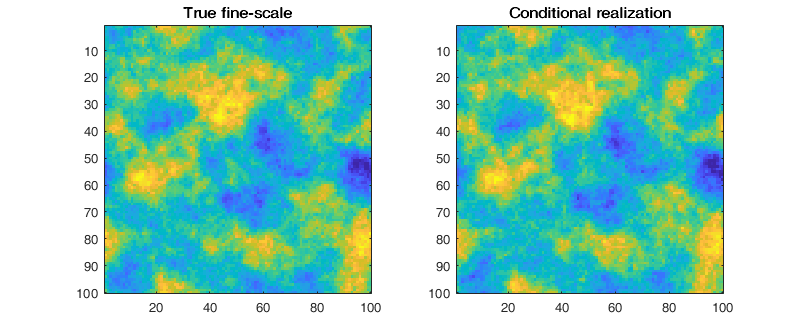

figure('pos',[0 0 800 330]); c_axis=[-3 3];
subplot(1,2,1); imagesc(z.x, z.y, z.true); caxis(c_axis); title('True fine-scale');
subplot(1,2,2);imagesc(z.x, z.y, zcs); caxis(c_axis); title('Conditional realization');

## Conditional Simulation

z.pt = sampling_pt(z,z.true,2,5);

Run function

[zcs,zh,S] = A2PK(z.x,z.y,z.pt,Z.true,G,covar,n_real);

Figure

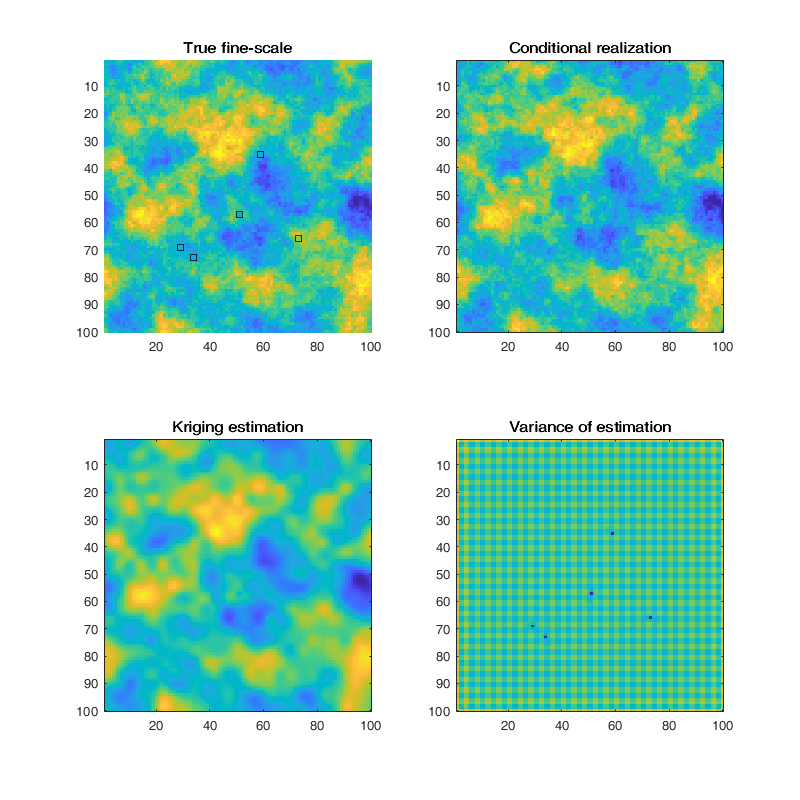

figure('pos',[0 0 800 800]); c_axis=[-3 3];
subplot(2,2,1); hold on; imagesc(z.x, z.y, z.true); scatter(z.pt.x,z.pt.y,[],z.pt.d,'s','filled','MarkerEdgeColor','k'); axis tight; caxis(c_axis); title('True fine-scale'); axis ij
subplot(2,2,2); imagesc(z.x, z.y, zcs); caxis(c_axis); title('Conditional realization');
subplot(2,2,3); imagesc(z.x, z.y, zh); caxis(c_axis); title('Kriging estimation');
subplot(2,2,4); imagesc(z.x, z.y, S); title('Variance of estimation');